# Nonlinear models

If the data comes from a physical process that is nonlinear, then we should use a nonlinear model. A nonlinear model will result in importance differences in the likelihood function and the posterior distribution. In the example below, we will also use some of the symbolic computing capabilities of MATLAB.

Consider a model of the form


$$f(x;w) = x - \frac{x^2}{w^2}$$


where $w$ is a scalar. Notice that $w$ does not appear linearly in the model.

mymodel = @(x,w) x - (x/w).^2;

Let's generate some synthetic data from this model. The data will contain noise with variance $\sigma^2 = 2$.

sigma2 = 2;

The ground truth value of $w$ is 1.8.

w_groundtruth = 1.8;

We generate $n=3$ observations at fixed values of $x$.

rng(0);
n = 3;
x = (1:n)';
y = mymodel(x,w_groundtruth) + sqrt(sigma2)*randn(size(x));

The likelihood function is


$$\frac{1}{(2 \pi \sigma^2)^{(n/2)}} \exp \left[ -\frac{1}{2\sigma^2} \sum_{i=1}^{n} \left(x_i - \frac{x_i^2}{w^2} - y_i \right)^2 \right]$$


To come up with an analytic formula for the likelihood function, we'll use some of the symbolic computing capabilities of MATLAB. The likelihood function is a function of $w$ which we define as a symbolic variable.

syms w
s = 0;
for i = 1:length(x)
  t = y(i) - mymodel(x(i), w);
  s = s + t*t;
end
s = 1/(2*pi*sigma2)^(n/2) * exp(-0.5/sigma2*s);
expand(s)

$$ans = \frac{50549281017715\,{\mathrm{e}}^{-\frac{191256929704985766832739687837077}{20282409603651670423947251286016}}\,{\mathrm{e}}^{-\frac{49}{2\,w^{4}}}\,{\mathrm{e}}^{\frac{107777768329753045}{4503599627370496\,w^{2}}}}{2251799813685248}$$

Let's plot this likelihood function. We can define this function inline by taking advantage of having the symbolic function `s` already available; otherwise it would be hard to define this function inline.

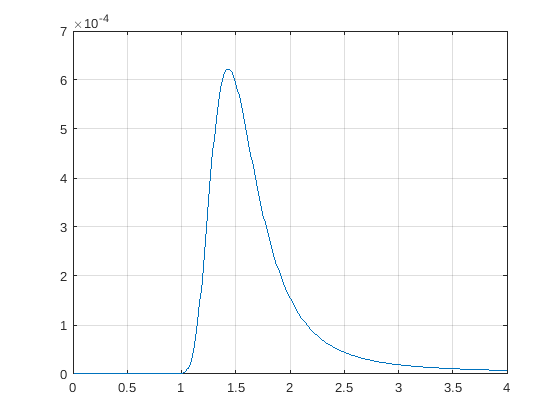

likef = @(w) double(subs(s));
w = (0.01:0.01:4);
l = likef(w);
plot(w,l);
grid on

Notice that the likehood function is not Gaussian, and it is not even symmetric about its peak. In addition, as $w$ goes toward infinity, the likehood function does not go to zero, as can be seen from the above analytic form of the likelihood function. Thus this likelihood function cannot be normalized to have area = 1 to try to interpret the likelihood function as a probability distribution.

We can also plot the negative log likelihood function. The location of the minimum obviously coincides with the location of the peak of the likelihood function, which is the maximum likelihood estimate.

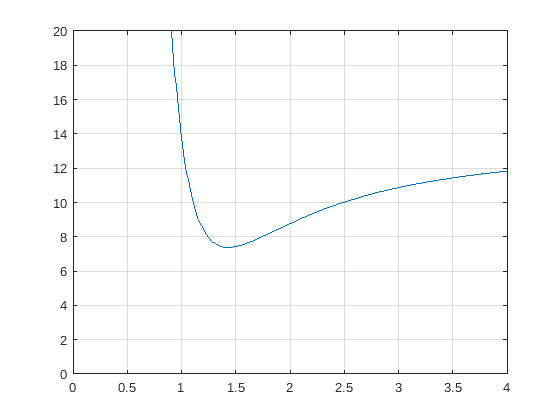

plot(w,-log(l));
axis([0 4 0 20])
grid on

### Taking it further

Rerun the demo with different data (by removing the `rng(0)` statement) to see different MLE estimates of $w$.

This demo only showed MLE for a nonlinear model. For Bayesian inference using the nonlinear model, see the live script `bayesian_simulation`.